the SVM model

ovo

rbf 模型  

% 假设X是特征矩阵，Y是标签向量
% 划分数据为训练集和测试集
[coeff, scoreS, ~] = pca(data');
X = scoreS(:, 1:2);
Y =groundTruth2;
cv = cvpartition(size(X, 1), 'HoldOut', 0.2); % 保留20%的数据用于测试
idx = cv.test;

% 划分训练集和测试集
XTrain = X(~idx, :);
YTrain = Y(~idx, :);
XTest = X(idx, :);
YTest = Y(idx, :);
XTrainStandardized = zscore(XTrain);
XTestStandardized = zscore(XTest);

线性

% 训练SVM模型
opts = struct('Optimizer', 'bayesopt', 'ShowPlots', true, ...
              'CVPartition', cvpartition(YTrain, 'KFold', 5), ... 
              'MaxObjectiveEvaluations', 20, ... 
              'AcquisitionFunctionName', 'expected-improvement-plus')

opts = 包含以下字段的 struct :
                  Optimizer: 'bayesopt'
                  ShowPlots: 1
                CVPartition: [1×1 cvpartition]
    MaxObjectiveEvaluations: 20
    AcquisitionFunctionName: 'expected-improvement-plus'


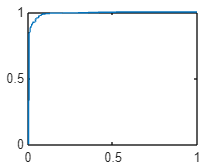

              
SVMModel_linear = fitcsvm(XTrainStandardized, YTrain, ...
        'KernelFunction', 'linear', ...
        'BoxConstraint', 1);


% 测试模型
[labels, score_lk] = predict(SVMModel_linear, XTestStandardized);
%绘制ROC曲线
[XsvmLin, YsvmLin, TsvmLin, AUCsvmLin] = perfcurve(YTest, score_lk(:,2),2);
plot(XsvmLin, YsvmLin);

figure;
% 计算准确率
accuracy = sum(YTest == labels) / length(YTest);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 96.11%


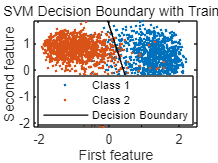


[x1Grid, x2Grid] = meshgrid(min(XTrainStandardized(:,1)):0.01:max(XTrainStandardized(:,1)), ...
                            min(XTrainStandardized(:,2)):0.01:max(XTrainStandardized(:,2)));
grid = [x1Grid(:), x2Grid(:)];

% 预测网格点的类别
[~, scores] = predict(SVMModel_linear, grid);

% 绘制数据点
figure;
gscatter(XTrainStandardized(:,1), XTrainStandardized(:,2), YTrain);
hold on

% 绘制决策边界
contour(x1Grid, x2Grid, reshape(scores(:,2), size(x1Grid)), [0, 0], 'k');

% 标记和标题
legend('Class 1', 'Class 2', 'Decision Boundary');
xlabel('First feature');
ylabel('Second feature');
title('Linear SVM Decision Boundary with Training Data');
hold off

RBF

%XTrainStandardized = zscore(XTrain);
%XTestStandardized = zscore(XTest);

opts = struct('Optimizer', 'bayesopt', 'ShowPlots', true, ...
              'CVPartition', cvpartition(YTrain, 'KFold', 5), ...
              'MaxObjectiveEvaluations', 30, 'AcquisitionFunctionName', ...
              'expected-improvement-plus');
SVMModel = fitcsvm(XTrainStandardized, YTrain, ...
                   'KernelFunction', 'rbf', ...
                   'BoxConstraint',1,...
                   'OptimizeHyperparameters', {'KernelScale'}, ...
                   'HyperparameterOptimizationOptions', opts, ...
                   'Standardize', true, 'Verbose', 1);

% 测试模型
[labels, score] = predict(SVMModel, XTestStandardized);

% 计算准确率
accuracy = sum(YTest == labels) / length(YTest);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);
%绘制ROC曲线
% 创建网格以绘制决策边界
[x1Grid, x2Grid] = meshgrid(min(XTrainStandardized(:,1)):0.01:max(XTrainStandardized(:,1)), ...
                            min(XTrainStandardized(:,2)):0.01:max(XTrainStandardized(:,2)));
grid = [x1Grid(:), x2Grid(:)];

% 预测网格点的类别
[~, scores] = predict(SVMModel, grid);

% 绘制数据点
figure;
gscatter(XTrainStandardized(:,1), XTrainStandardized(:,2), YTrain);
hold on

% 绘制决策边界
contour(x1Grid, x2Grid, reshape(scores(:,2), size(x1Grid)), [0, 0], 'k');

% 标记和标题
legend('Class 1', 'Class 2', 'Decision Boundary');
xlabel('First feature');
ylabel('Second feature');
title('SVM Decision Boundary with Training Data');
hold off



figure;
[XsvmLin, YsvmLin, TsvmLin, AUCsvmLin] = perfcurve(YTest, score(:,2),2);
plot(XsvmLin, YsvmLin);
xlabel('False positive rate') 
    ylabel('True positive rate')
bestParams = SVMModel.HyperparameterOptimizationResults.XAtMinObjective;


%bestC = bestParams.BoxConstraint;
bestGamma = bestParams.KernelScale;

% 显示最佳超参数
%fprintf('Best C (BoxConstraint): %f\n', bestC);
fprintf('Best Gamma (KernelScale): %f\n', bestGamma);
fprintf(' AUC: %f\n', AUCsvmLin);

这是MATLAB中用于训练支持向量机（SVM）模型的代码片段，其中`fitcsvm`函数用于创建SVM模型。以下是代码中每个参数的解释：

- `XTrainStandardized`：这是训练数据的特征矩阵，已经进行了标准化处理。通常，SVM需要输入特征的标准化或归一化，以确保不同特征的尺度不会影响模型的训练。

- `YTrain`：这是与训练数据对应的目标标签向量，用于指示每个训练样本的类别。

- `'KernelFunction', 'rbf'`：这是SVM模型的核函数。在这里，使用了RBF（径向基函数）核函数，也称为高斯核函数。RBF核函数在SVM中常用于处理非线性问题，因为它具有很强的表示能力。

- `'OptimizeHyperparameters', {'BoxConstraint', 'KernelScale'}`：这是一个选项，指示SVM模型是否应该在训练过程中通过交叉验证来选择最佳的超参数。在这里，模型会尝试优化`BoxConstraint`（正则化参数C）和`KernelScale`（RBF核函数的尺度参数）这两个超参数。

- `'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName', 'expected-improvement-plus', 'MaxObjectiveEvaluations', 30, 'ShowPlots', true)`：这是用于配置超参数优化的选项。具体参数解释如下：

- `'AcquisitionFunctionName'`：指定用于超参数优化的采集函数的名称。在这里，使用的是`'expected-improvement-plus'`，它是一种用于选择下一个超参数设置的算法。

- `'MaxObjectiveEvaluations'`：指定了在超参数优化过程中允许的最大目标函数评估次数。在这里，设置为30次。

- `'ShowPlots'`：设置为true，以在超参数优化过程中显示优化进度图。

- `'Standardize', true`：这是一个选项，指示模型是否应该在训练之前标准化训练数据。在这里，设置为true，表示将使用标准化的数据来训练模型。

- `'Verbose', 1`：这是一个选项，指示模型是否应该产生训练过程的详细信息。在这里，设置为1，表示要输出详细信息，以便监视训练进度